# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder, any output images you might have saved and this livescript file.

Since we need to access the functions and data folder the first step is to add these two locations to MATLAB's path.

addpath('./functions');
addpath('./data');

# Lab 2: Learning and convolutional neural networks

## 2.1 Learning a Linear Classifier

In this part, we will try to learn a linear classifier for blood cell detection. Note that the classifier could also be viewed as a minimal neural network consisting of three parts: a scalar product node (or fully-connected node), a constant (or bias) term and a logistic sigmoid function. To find good parameters we will try to minimize the negative log-likelihood over a small training set.

The output from our classifier is a probability p for the input patch being centered at a cell centre. The sigmoid function will make sure that 0 ≤ p ≤ 1. To be more precise the output is


$$p=\frac{e^y }{1+e^y }\;\;\;\;\textrm{where}\;\;\;\;y=I\cdot \omega +\omega_0$$


Instead of testing a bunch of manually chosen w’s and w_0’s, we will try to learn good values for all the parameters. This requires training examples, that you find in cell_data.mat.

## Ex 2.1 

## Load the data using

load cell_data.mat

It loads a structure, cell_data, with two fields, `fg_patches` and `bg_patches`, corresponding to positive (centered blood cells) negative examples respectively.

## Ex 2.2 

Create two new variables, examples and labels. The variable examples should be a cell structure containing all the patches (both positives and negatives) and labels should be an array with the same number of elements such that `labels(i) = 1` if` examples{i}` is a positive example, and `labels(i) = 0` otherwise.

% Your code here

% Just simply add them together with concatenation...
examples = [cell_data.fg_patches, cell_data.bg_patches];
labels = [ones(1,200), zeros(1,200)];

## Ex 2.3

Split the data into training,` (examples_train, labels_train)`, and validation,` (examples_val, labels_val)`. The two should have a similar structure to examples and labels. Write on the report which percentage of the data you used for validation. Also, the splitting of the data into the two sets should be done in a random manner, for example, using randperm. 

**Percentage of data used for training**: alpha%

**Percentage of data used for validation**: 1-alpha%

% Your code here
alpha = 0.75;

% Randomly choose out of the 400 to train
n_train = randperm(length(examples),round(length(examples)*alpha));
n_val = [];
for i=1:length(examples)
    if any(n_train(:)==i)
        continue
    else
        n_val = [n_val i];
    end
end


% Extract trainin set given n_train
examples_train = examples(n_train);
labels_train = labels(n_train);

% Extract validation set given n_val
examples_val = examples(n_val);
labels_val = labels(n_val);


## 2.2 Training the classifier

We will try to find parameters that minimize the negative log-likelihood on the training data. More precisely,


$$L\left(\theta \right)=\sum_{i\in S_+ } -\ln \left(p_i \right)+\sum_{i\in S_- } -\ln \left(1-p_i \right)=\sum_i L_i \left(\theta \right)$$


where $p_i$ refers to the classifier output for the ith training example. As in the lectures we will refer to the terms here as the partial loss $L_i$.

Before doing the next exercise, you need to work out how to compute the gradient of the partial loss $L_i$.

## Ex 2.4

Make a function

        `[wgrad, w0grad] = partial_gradient(w, w0, example_train, label_train)`

that computes the derivatives of the partial loss L_i with respect to each of the classifier parameters. Let the output wgrad be an array of the same size as the weight image, w (and let w0grad be a number). 

At each iteration of stochastic gradient descent, a training example, i, is chosen at random. For this example the gradient of the partial loss, L_i , is computed and the parameters are updated according to this gradient. The most common way to introduce the randomness is to make a random reordering of the data and then going through it in the new order. One pass through the data is called an epoch.

## Ex 2.5

Make a function

        `[w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train)`

that performs one epoch of stochastic gradient descent

## Ex 2.6 

Initialize `w = s * randn(35,35);`, with `s = 0.01` and `w0 = 0;` and run 5 epochs on your training examples. Plot w after each epoch (or after each iteration if you are curious), to get a sense of what is happening. Also, try using different `s={10,1,0.1,0.01}` and plot w after 5 epochs for each value of s. Include on the report visualizations of w for the different values of s, along with an written explanation of what is happening.

w for s=0.01

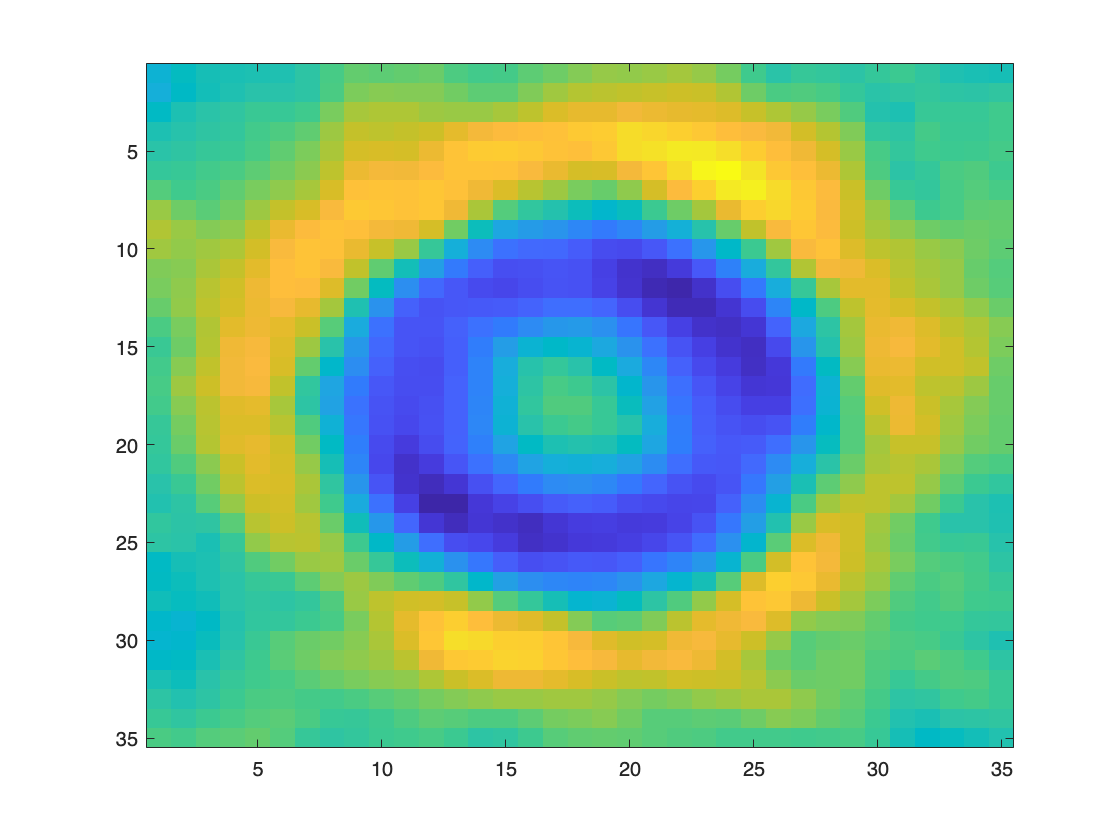

w for s=0.10

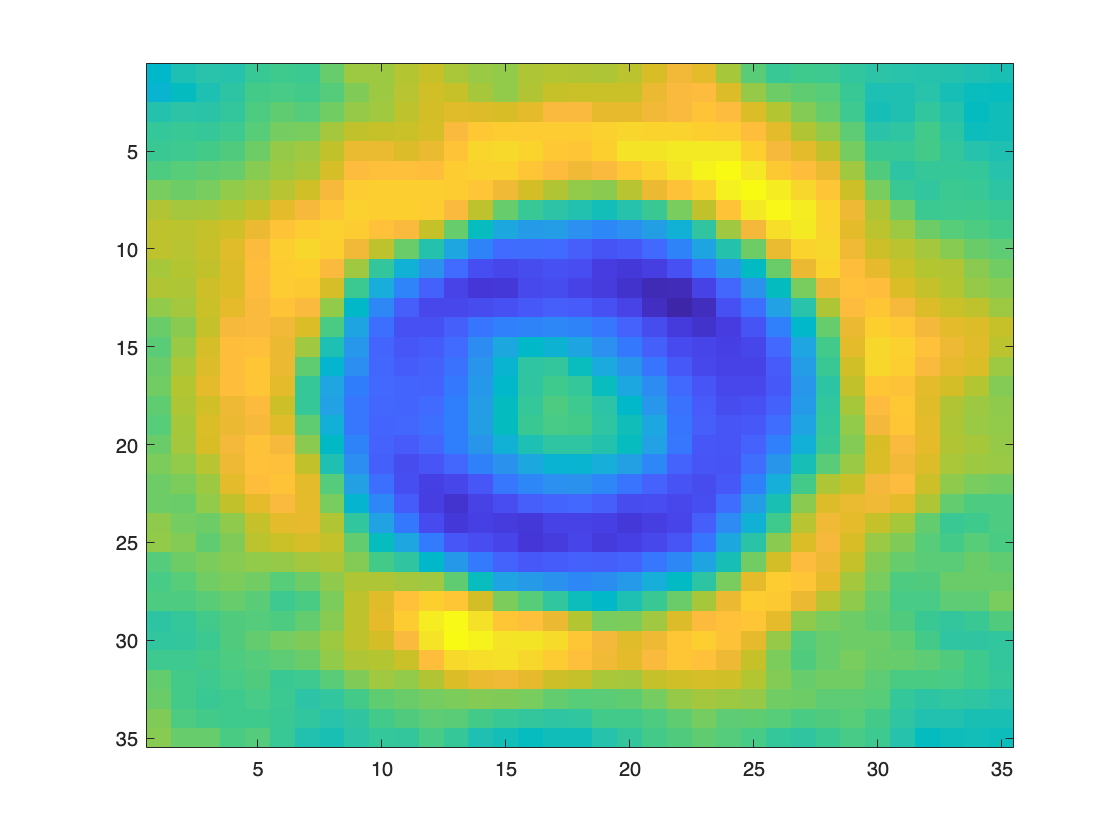

w for s=1.00

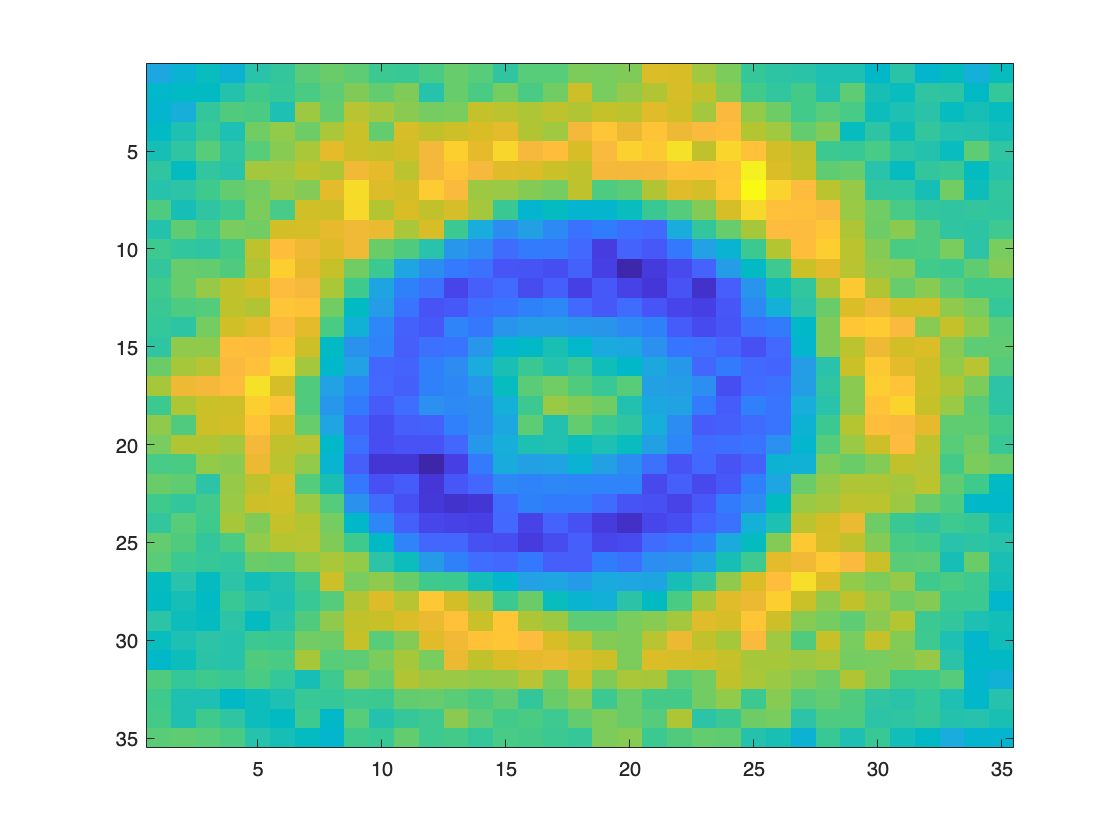

w for s=10.00

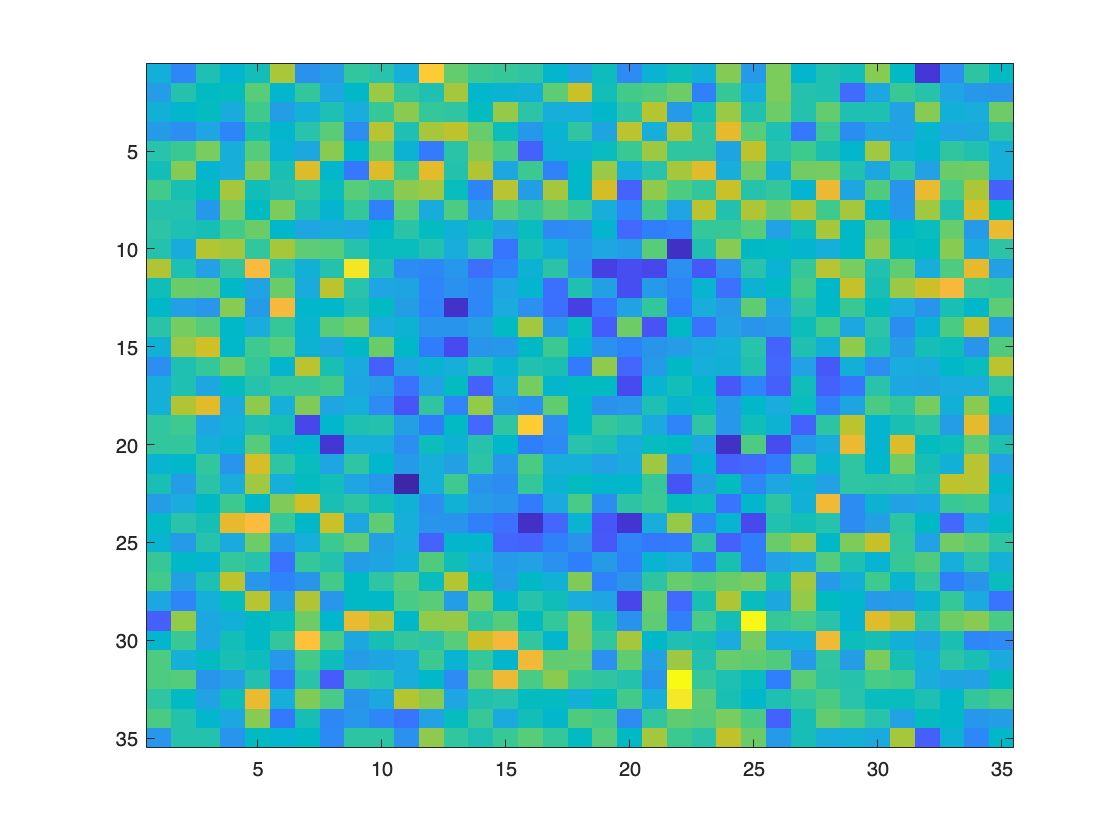

w for s=0.01

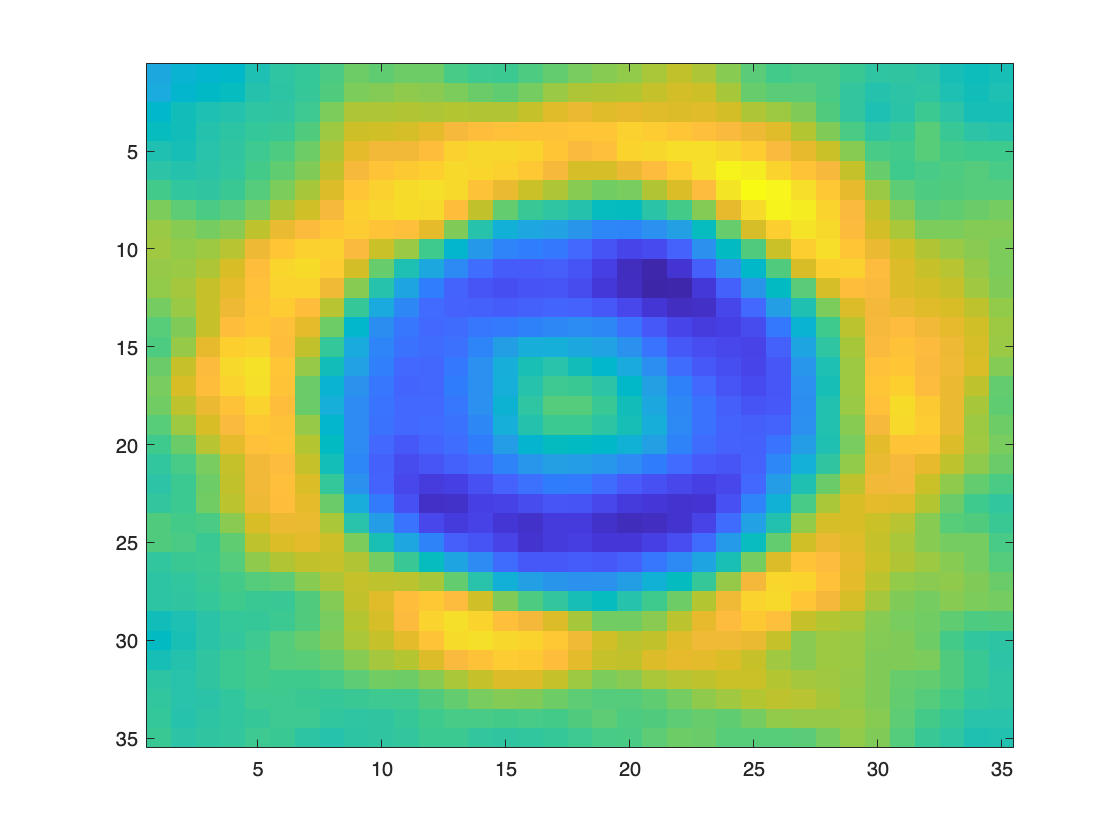

% your code here
s = [0.01, 0.1, 1, 10, 0.01];
lrate = 0.7;

% Iterate through the different s
for i=1:length(s)

    % initialize w and bias w0
    w0 =0;
    w = s(i) * randn(35,35);

    % run 5 epochs with the given initial w and w0
    for j=1:5
        [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train);
    end

    % plot w after 5 epochs
    figure()
    fprintf('w for s=%.2f',s(i))
    imagesc(w)
end

**Your written answer here:**

As we can see, after 5 epochs the w begins to mimic a template for a cell. This template w is used to determine if an image I is similar to a cell or not, i.e how to classify the image.

For larger s, the initial guess for the template cell w varies more. By having larger values in w, we essentially have a initial guess that is further from the local minima in the other examples with lower s. This will allow the minimization to find other local minima (further away) and thus a different solution to w. Even though the w for s=10 looks alot like noise, it doesn't necessarily imply worse performance for the classifyer...

If the learning rate (or step length) is large enough, other local minima might be found which improves performance. Arguably, a larger stepsize would be benneficial when the guess is far from the solution.

/ Nicholas Granlund 

## Exercise 2.7

As said before, at each iteration of stochastic gradient descent, a training example is chosen at random. Check what happens to w after 5 epochs when that training example is not chosen randomly but in sequence, i.e. first `i = 1`, then `i = 2`, and so on. Include on the report a visualization of w for this case. (Don’t forget to change back your function to a random choice of i after this exercise).

You can display the resulting filters inside this livescript notebook using the function imagesc.

w for s=0.01

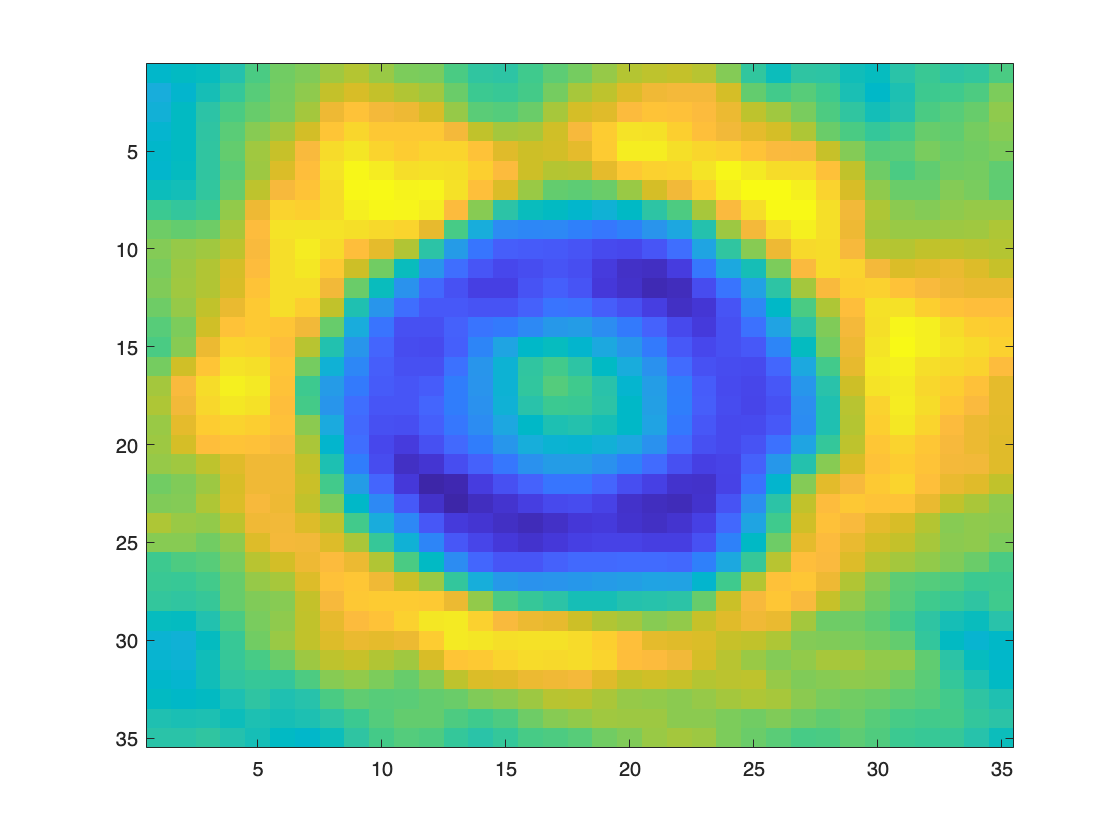

w for s=0.10

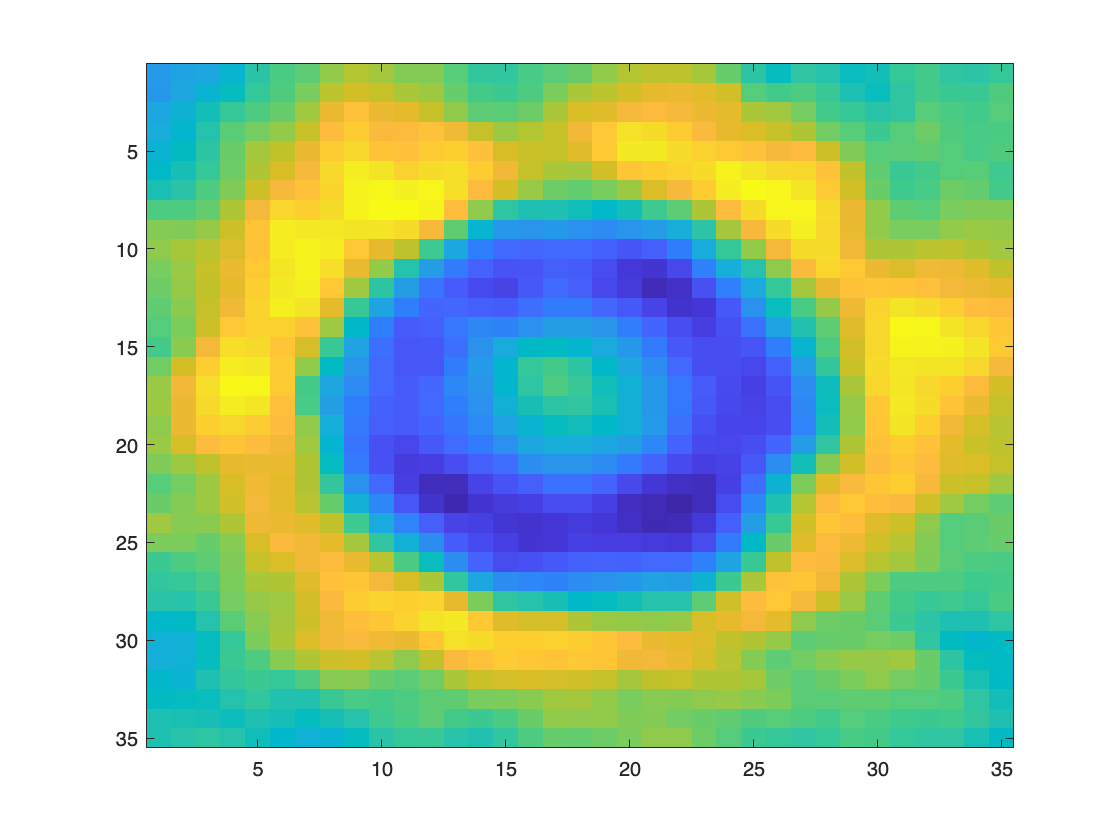

w for s=1.00

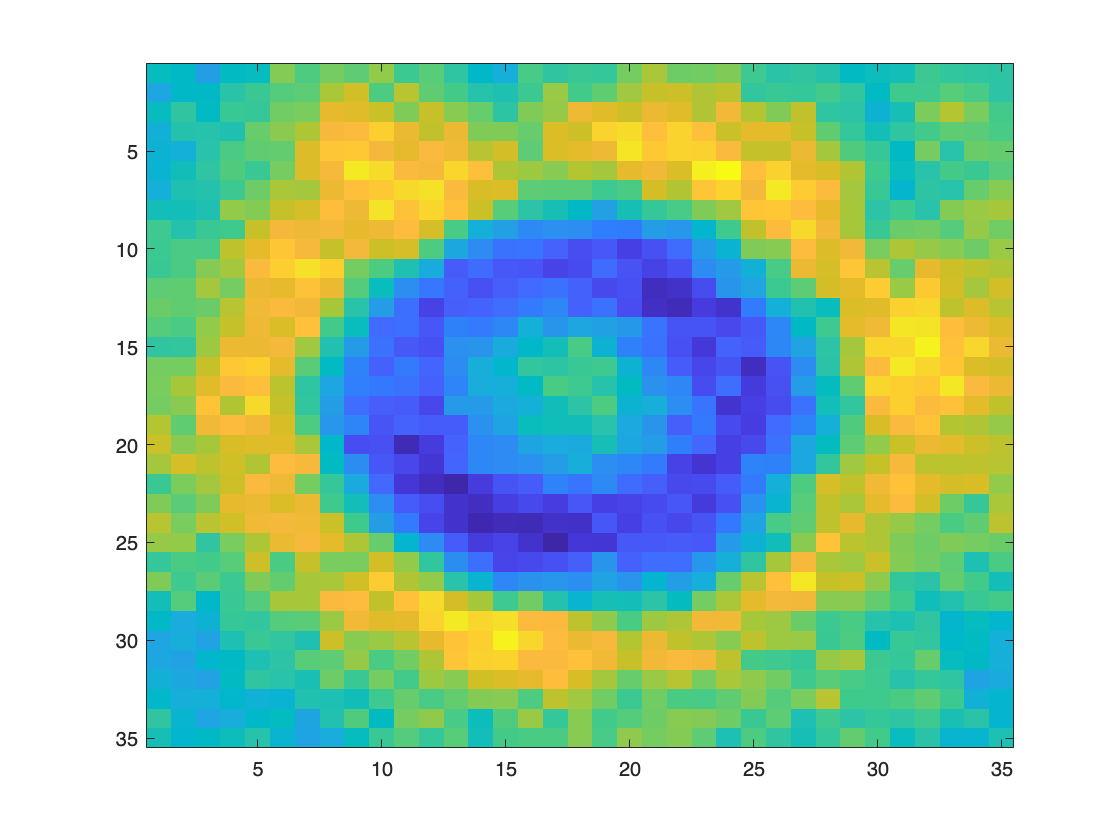

w for s=10.00

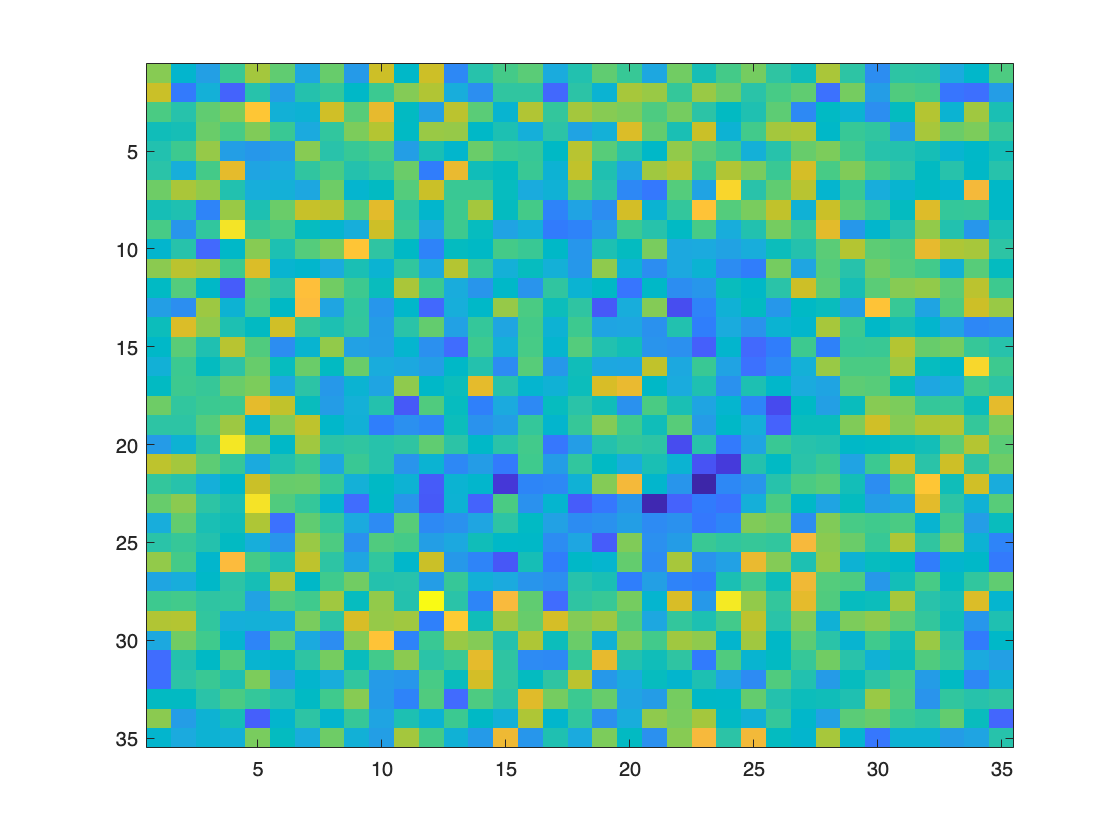

% your code here
s = [0.01, 0.1, 1, 10];
lrate = 0.7;

% Iterate through the different s
for i=1:length(s)

    % initialize w and bias w0
    w0 =0;
    w = s(i) * randn(35,35);

    % run 5 epochs sequencially with the given initial w and w0
    for j=1:5
        [w, w0] = process_epoch_seq(w, w0, lrate, examples_train, labels_train);
    end

    % plot w after 5 epochs
    figure()
    fprintf('w for s=%.2f',s(i))
    imagesc(w)
end

% change back to random images...
s = 0.01;
lrate = 0.7;

% initialize w and bias w0
w0 =0;
w = s * randn(35,35);

% run 5 epochs with the given initial w and w0
for j=1:5
    [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train);
end

## Ex 2.8 

Make a function

        `predicted_labels = classify(examples_val,w,w0);`

that applies the classifier to the example data. After that, use it on `examples_train` and examples_val and check how much accuracy it gets for each by comparing the predicted labels with `labels_train` and `labels_val` respectively. Write on your report the highest accuracy you were able to achieve in the training and validation data. Hint: train the classifier for longer than 5 epochs to make sure that it converges.

When you have defined the function run the following code.

predicted_labels = classify(examples_val,w,w0);
correct = sum(predicted_labels==labels_val);
accuracy = 100*correct/length(labels_val);
fprintf(["Validation Accuracy: "]+accuracy+["%%"])

Validation Accuracy: 91%

**Write the highest accuracy you were able to get here:**

Highest: 91%

Lowest: 51%

Most frequent: ≈81%

## Ex 2.9

The data for training this classifier consists on only 400 examples (less if you consider that you have split it into training and validation). To achieve higher accuracy it might be useful to perform some data augmentation before the training. In this exercise you will increase the number of elements in the training examples by M times. Make a function

        `[examples_train_aug,labels_train_aug] = augment_data(examples_train,labels_train,M)`

that takes each sample of the original training data and applies M random rotations (you can use Matlab function imrotate), from which result M new examples. Store these new examples in examples_train_aug and their corresponding labels in labels_train_aug. Train the classifier with this augmented data and write on your report the new values for accuracy on the training and validation examples.

% Your code here

% chose M times augmentation of a picture
M = 2;

% Augment the data
[examples_train_aug,labels_train_aug] = augment_data(examples_train,labels_train,M);

% Define parameters
s = 0.01;
lrate = 0.7;

% initialize w and bias w0
w0 =0;
w = s * randn(35,35);

% run 5 epochs with the given initial w and w0 on augmented data
for j=1:5
    [w, w0] = process_epoch(w, w0, lrate, examples_train_aug, labels_train_aug);
end

% Calculate calidation accuracy
predicted_labels = classify(examples_val,w,w0);
correct = sum(predicted_labels==labels_val);
accuracy = 100*correct/length(labels_val);
fprintf(["Validation Accuracy: "]+accuracy+["%%"])

Validation Accuracy: 84%

**Write the highest accuracy you were able to get here:**

Highest: 91%

Lowest: 52%

Most frequent: ≈84%

## 2.3 Convolutional neural networks

In the last part, your task is to train convolutional neural networks using Matlab.

## `Ex 2.10 `

Run the following cell

[imgs, labels] = digitTrain4DArrayData;

to load a dataset of images of digits into Matlab. (Make sure you have the Deep Learning toolbox installed). You will find the 5000 digit images in imgs. Plot a few of them to see what the data looks like.

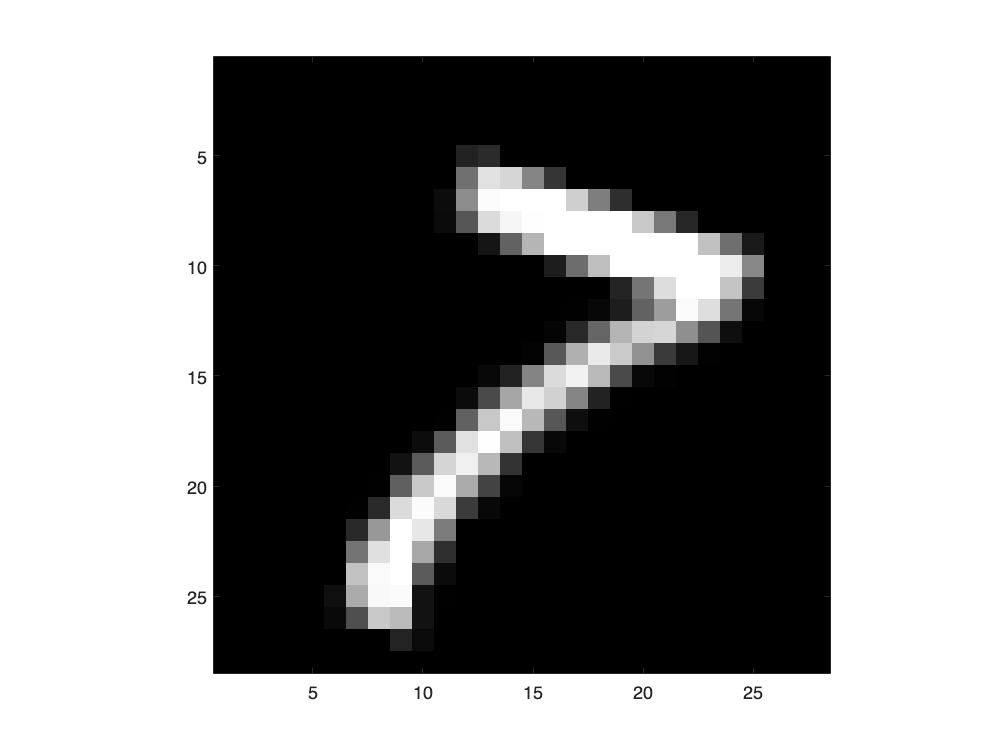

N = 3210; % We have 5000 images so any number between 1 and 5000 works.
img = imgs(:,:,:,N);
imagesc(img), axis image, colormap gray

The next step is to define a network for classification. In Matlab, you do this by simply giving an array of the layers. For example, this would be a linear classifier similar to the one you trained for cells:

        layers = [

            imageInputLayer([35 35 1]);

            fullyConnectedLayer(1);

            softmaxLayer();

            classificationLayer()];

## Ex 2.11 

Make a function

        `layers = basic_cnn_classifier()`

that implements the following network in Matlab:

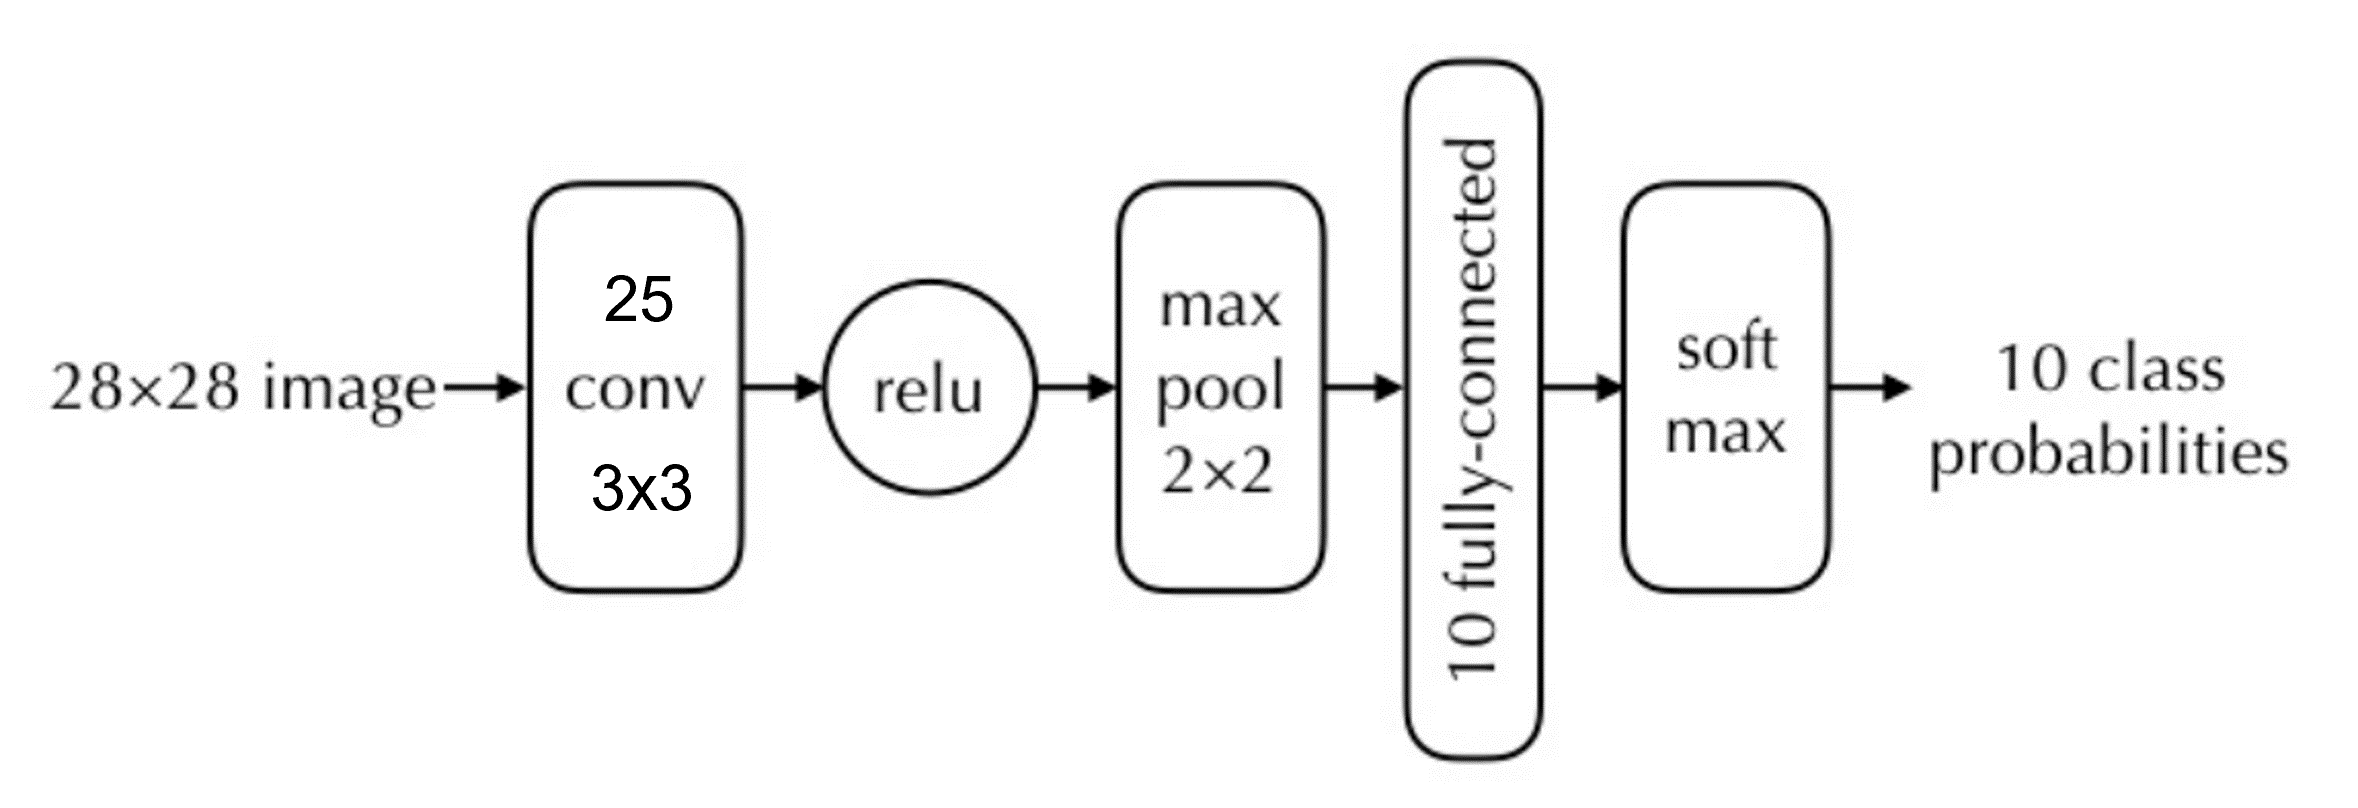

Apart from the layers above the functions `convolution2dLayer`, `reluLayer` and `maxPooling2dLayer` will be useful. Note that you have to set the *stride* for max pooling to 2 to get the expected downsampling.

When you have written the function run the following cell:

layers = basic_cnn_classifier();

## Ex 2.12 

Create a set of training options telling Matlab to use stochastic gradient descent with momentum (SGDM), for the optimization:

        `options = trainingOptions('sgdm');`

Now train the network (using default parameters) by running

        net = trainNetwork(imgs, labels, layers, options)

% Your code here
options = trainingOptions('sgdm');
net = trainNetwork(imgs, labels, layers, options)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        7.81% |       2.3006 |          0.0100 |
|       2 |          50 |       00:00:01 |       46.88% |       1.8064 |          0.0100 |
|       3 |         100 |       00:00:02 |       64.06% |       1.2163 |          0.0100 |
|       4 |         150 |       00:00:03 |       60.16% |       1.0490 |          0.0100 |
|       6 |         200 |       00:00:04 |       66.41% |       1.0299 |          0.0100 |
|       7 |         250 |       00:00:05 |       67.19% |       1.0983 |          0.0100 |
|       8 |         300 |  

net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


## Ex 2.13 

Try the network on a few of the training images. You can use `net.predict(img)` to get the ten output probabilities or `net.classify(img)` to get the most probable class.

% Your code here

img1 = imgs(:,:,:,413);         % number 1
net.predict(img1)               % The network has some uncertainty, but most probable 1

ans = 1×10 single row vector
    0.0000    0.9963    0.0002    0.0014    0.0000    0.0012    0.0006    0.0000    0.0003    0.0000


img2 = imgs(:,:,:,9);         % number 7  
net.predict(img2)             % The network is fairly certain this is a 7

ans = 1×10 single row vector
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000


img3 = flip(imgs(:,:,:,1149));  % number 9 flipped
net.predict(img3)               

ans = 1×10 single row vector
    0.0205    0.0000    0.0000    0.0047    0.0012    0.0000    0.8916    0.0000    0.0820    0.0000


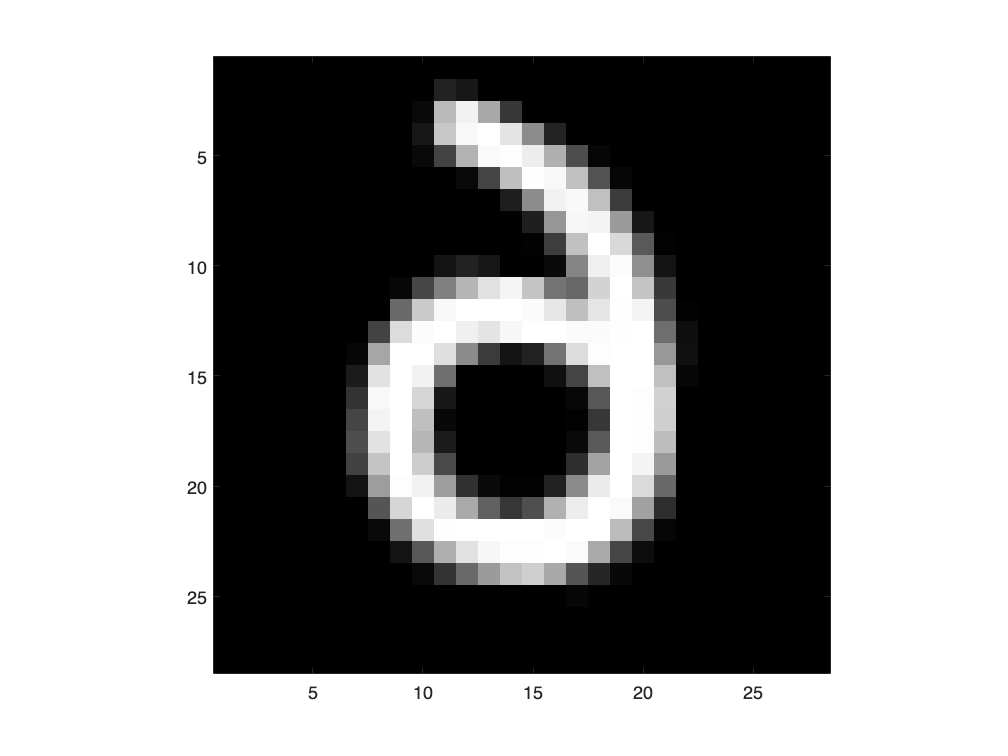

% Funny enough, a 9 flipped to a mirrored six will classify most certainly as a 6.
imagesc(img3), axis image, colormap gray

## Ex 2.14 

Work out how many trainable parameters your network contains. Include the answer in your submission. If you explore what the data structure net actually contains, you can find the answer there as well. Note that the convolution layer does not use padding so the output from the convolution layer is smaller than the input.

**Write your answer here:**

- Convolutional layer (25 filters, 3x3 filter size):  (3 * 3  + 1) * 25= 250 parameters

- ReLU layer: 0 parameters

- MaxPool: 0 parameters

- Fully connected layer: (4225 * 10) + 10 = 42260 parameters

- Final softmax layer: 0 parameters

% By analysing the network we get directly 42510 trainable parameters
analyzeNetwork(net.Layers)


Total: 250 +  42260 = **42510 paramters**

/ Nicholas Granlund

## Ex 2.15 

Matlab prints a lot of output, for example the accuracy on the training set. Recall from the lectures that this number is not very good for judging the quality of a classifier. Instead we should save a subset of the data as a validation set, that we can use to evaluate the trained network. 

Divide the data into training `imgs` and `labels` into new variables `imgs_train, labels_train, imgs_val, labels_val`.

% Your code here
alpha = 0.75;

% Randomly choose out of the 5000 to train
n_train = randperm(length(imgs),round(length(imgs)*alpha));
n_val = [];
for i=1:length(imgs)
    if any(n_train(:)==i)
        continue
    else
        n_val = [n_val i];
    end
end


% Extract training set given n_train
imgs_train = imgs(:,:,:,n_train);
labels_train = labels(n_train);

% Extract validation set given n_val
imgs_val = imgs(:,:,:,n_val);
labels_val = labels(n_val);

Make a function 

        `net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val) `

that runs a few epochs of training and then evaluates the accuracy on the validation set. In this case, Matlab has given us a separate test set, so we don’t have to save images for that purpose. *Matlab hints:* You can run multiple images at once by stacking them along the fourth dimension. If you want to continue training the same network you can run

        `net = train_classifier(net.Layers, imgs_train, labels_train, imgs_val, labels_val)`

% Your code here
net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       13.28% |       2.2936 |          0.0100 |
|       2 |          50 |       00:00:00 |       42.19% |       1.8595 |          0.0100 |
|       4 |         100 |       00:00:01 |       57.03% |       1.2295 |          0.0100 |
|       6 |         150 |       00:00:02 |       60.16% |       1.1358 |          0.0100 |
|       7 |         200 |       00:00:03 |       59.38% |       1.0875 |          0.0100 |
|       9 |         250 |       00:00:04 |       66.41% |       1.0677 |          0.0100 |
|      11 |         300 |  

**Ex 2.16 **

To run a convolutional neural network we have to perform a massive amount of computations. Hence it is very important to consider the computational load when designing a network. For the network below, compare (roughly) the time consumption of the blue and the red layers. You can ignore effects of padding. Include your answer and your motivation in your submission.

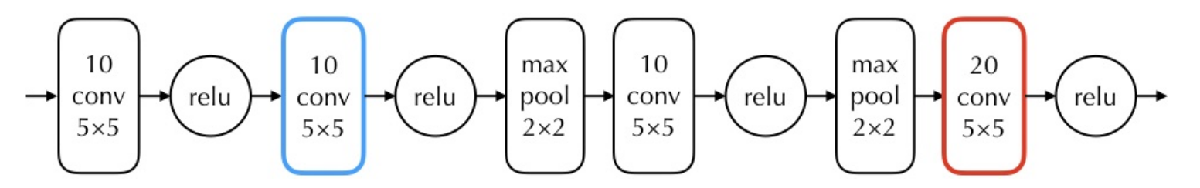

**Write your answer here:**

If we only consider the amount of multiplications to determine the computational complexity. We get:

For the blue 10 5x5 conv layer.  We have an input with dimensions  d*d. 

Running this through the blue layer we get roughly:    (d*d*10)*(5*5*10) = 2500*d*d computations

Now for the red 20 5x5 layer we have different input size due to the maxpooling. we have two which will decrease the input size to d/4*d/4

Running this through the red layer we get roughly:    (d/4*d/4*10)*(5*5*20) = 312.5*d*d computations

blue / red = 8.00.    8x more computations in the blue layer

Therefor there are fewer computations done by the red conv layer compared to the blue conv layer

/ Nicholas Granlund

## Ex 2.17

Replace the blue box of the network in the figure above by a sequence of two layers of 10 3 × 3 convolutional filters. What changes in terms of network parameters, time consumption and accuracy? Again, you are not supposed to implement the network.

**Write your answer here:**

1x blue conv layer:          (d*d*10) * 1 * (10 * 5 * 5 )  = 2500*d*d

2x blue conv layer:          (d*d*10)*  2 * (10 * 3 * 3 )  = 1800*d*d

The 2x blue conv layer has fewer parameters. It will also have a lower time consumption. Having a small number of parameters may impact the perfromance/accuracy in a negative way. It does however reduce the risk of overfitting data.

The benefit of having a one 10 5x5 conv layer is that it can detect large features, for example the circle in the number "6" or the sharp angle in the number "7". However, by introducing two 10 3x3 conv layers we can still obtain the ability to detect large features. The first 10 3x3 conv layer will detect large features and the second following 10 3x3 conv layer will detect smaller features within these large features.

With this in mind, 2 10 3x3 conv layers may be preferable. However one should consider placing a maxpooling filter or ReLU between the two conv layers to increase accuracy further...

/ Nicholas Granlund

## Ex. 2.18

Make a copy of basic_cnn_classifier.m and name it better_cnn_classifier.m. Try modifying the network by adding more layers. Also experiment with the training options. How much can you improve the results?

% Your code here
layers = better_cnn_classifier();

% train network
options = trainingOptions('sgdm', ...
                           MaxEpochs=12);% <-- Set max epochs to 12 to save time...                         
better_net = trainNetwork(imgs_train, labels_train, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       12.50% |       2.2962 |          0.0100 |
|       2 |          50 |       00:00:04 |       43.75% |       1.8256 |          0.0100 |
|       4 |         100 |       00:00:08 |       65.62% |       0.9767 |          0.0100 |
|       6 |         150 |       00:00:12 |       79.69% |       0.6491 |          0.0100 |
|       7 |         200 |       00:00:17 |       95.31% |       0.2066 |          0.0100 |
|       9 |         250 |       00:00:21 |       97.66% |       0.1047 |          0.0100 |
|      11 |         300 |  


% Classify validation images on trained network
label_prediction = classify(better_net,imgs_val);
    
% Determine accuracy
accuracy = sum(label_prediction == labels_val)/numel(labels_val);

% Print results
fprintf('\n\nAccuracy on validation set: %.2f%%',accuracy*100)



Accuracy on validation set: 95.92%

We can se by adding 2 convolutional layers we can drastically increase the performance of the network, it needs fewer epochs to improve and rather quickly reaches ≈100% accuracy on mini batches. It does however take more time to train since we have increased the number of trainable parameters in our network quite drastically...

/ Nicholas Granlund

## Ex 2.19 

Load the builtin test images using

        `[imgs_test, labels_test] = digitTest4DArrayData;`

Run the network on all the test images. You apply the network to an image using

        pred = net.classify(image)

Compute precision and recall for each of the 10 classes and include these in your submission. The definitions of precision and recall can be found in the lecture notes chapter 4.

%Your code here
[imgs_test, labels_test] = digitTest4DArrayData;

% OBS NOTE TO EXAMINER
% I thought it was unclear wether to use the basic_cnn_classifier() or the
% new better_cnn_classifier()...
% I did use the basic_cnn_classifier() network for Ex 2.19 and 2.20

% Train the network on all the test images
layers = basic_cnn_classifier();
options = trainingOptions('sgdm');
net = trainNetwork(imgs_test, labels_test, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       11.72% |       2.3091 |          0.0100 |
|       2 |          50 |       00:00:01 |       58.59% |       1.6591 |          0.0100 |
|       3 |         100 |       00:00:01 |       50.78% |       1.2707 |          0.0100 |
|       4 |         150 |       00:00:02 |       73.44% |       0.9090 |          0.0100 |
|       6 |         200 |       00:00:03 |       61.72% |       1.1163 |          0.0100 |
|       7 |         250 |       00:00:04 |       70.31% |       1.0246 |          0.0100 |
|       8 |         300 |  

% Classify test images
label_classification = double(classify(net,imgs_test))-1;
labels_test = double(labels_test)-1;

% Iterate through the possible classes
for number=0:9
    
    % Number of examples classified as class 
    indexes = find(label_classification==number);
    
    % Number of examples classified as class A
    nr_of_examples_classified_as_class_A = length(indexes);
    
    % Number of examples from class A
    nr_of_examples_from_class_A = length(find(labels_test==number));
    
    % Start counter for correctly classified labels
    nr_of_correctly_classified_as_class_A = 0;
    for i=1:length(indexes)
        if labels_test(indexes(i)) == number
            nr_of_correctly_classified_as_class_A =nr_of_correctly_classified_as_class_A + 1;
        end
    end
    
    % Calculate precision and recall
    precision = nr_of_correctly_classified_as_class_A / nr_of_examples_classified_as_class_A;
    recall = nr_of_correctly_classified_as_class_A / nr_of_examples_from_class_A;

    % Print results
    fprintf('\n\n precision for class "%.0f": %.2f%%', number, precision*100)
    fprintf('\n recall for class    "%.0f": %.2f%%\n\n', number, recall*100)
    fprintf('-----------------------------------')
end



 precision for class "0": 99.19%


 recall for class    "0": 97.80%



-----------------------------------



 precision for class "1": 98.81%


 recall for class    "1": 99.60%



-----------------------------------



 precision for class "2": 96.83%


 recall for class    "2": 97.60%



-----------------------------------



 precision for class "3": 90.71%


 recall for class    "3": 97.60%



-----------------------------------



 precision for class "4": 98.80%


 recall for class    "4": 99.20%



-----------------------------------



 precision for class "5": 99.15%


 recall for class    "5": 92.80%



-----------------------------------



 precision for class "6": 98.01%


 recall for class    "6": 98.60%



-----------------------------------



 precision for class "7": 100.00%


 recall for class    "7": 98.60%



-----------------------------------



 precision for class "8": 97.80%


 recall for class    "8": 97.60%



-----------------------------------



 precision for class "9": 98.59%


 recall for class    "9": 97.80%



-----------------------------------

## Ex 2.20

Save three of the failure cases with names indicating what digit they were mistaken for. Include these in your submission. You can use imwrite(img, ’mistaken_as_5.png’) to save an image if it is correctly scaled. Have a look at the file before submitting it, so it looks right.

You can load and display the images here using imagesc:

% Your code here

% This is a 9 which was classified as a 3
wrong_digit_1 = imgs_test(:,:,:,4969);

% the net seems rather confident that it is a 3...
net.predict(wrong_digit_1)    

ans = 1×10 single row vector
    0.0680    0.0003    0.0185    0.7808    0.0016    0.0246    0.0002    0.0001    0.0025    0.1032


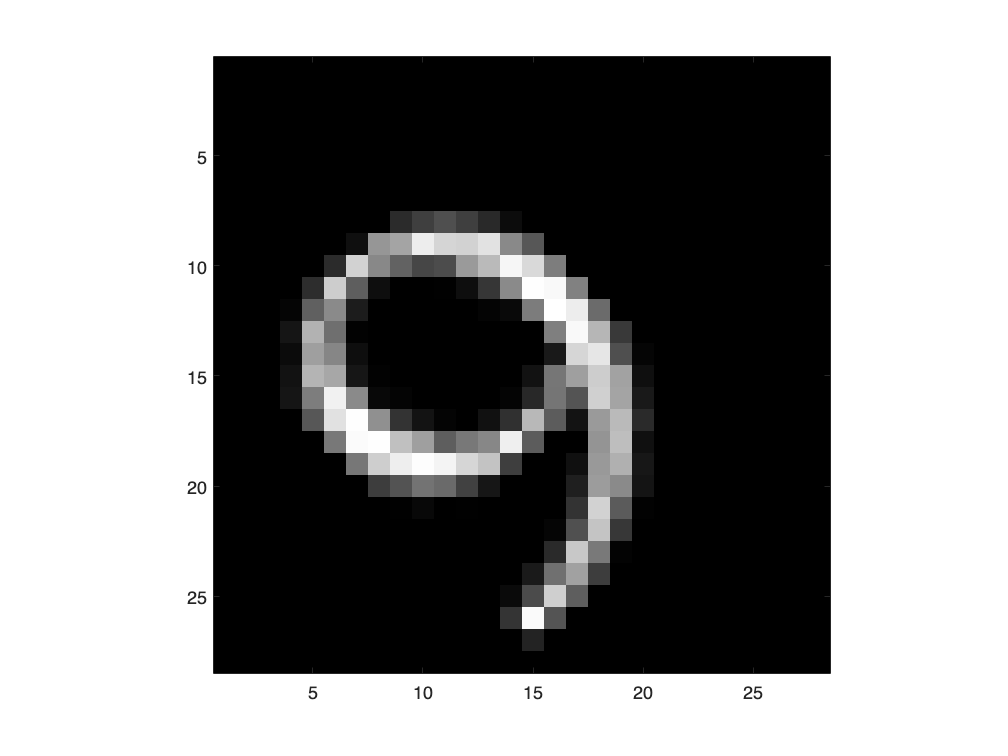

imagesc(wrong_digit_1), axis image, colormap gray

% This is a 0 which was classified as a 6
wrong_digit_2 = imgs_test(:,:,:,44);

% However, the net is only ≈40% certain that it is a 6...
net.predict(wrong_digit_2)  

ans = 1×10 single row vector
    0.0591    0.2502    0.0064    0.1255    0.0000    0.1316    0.4095    0.0000    0.0175    0.0000


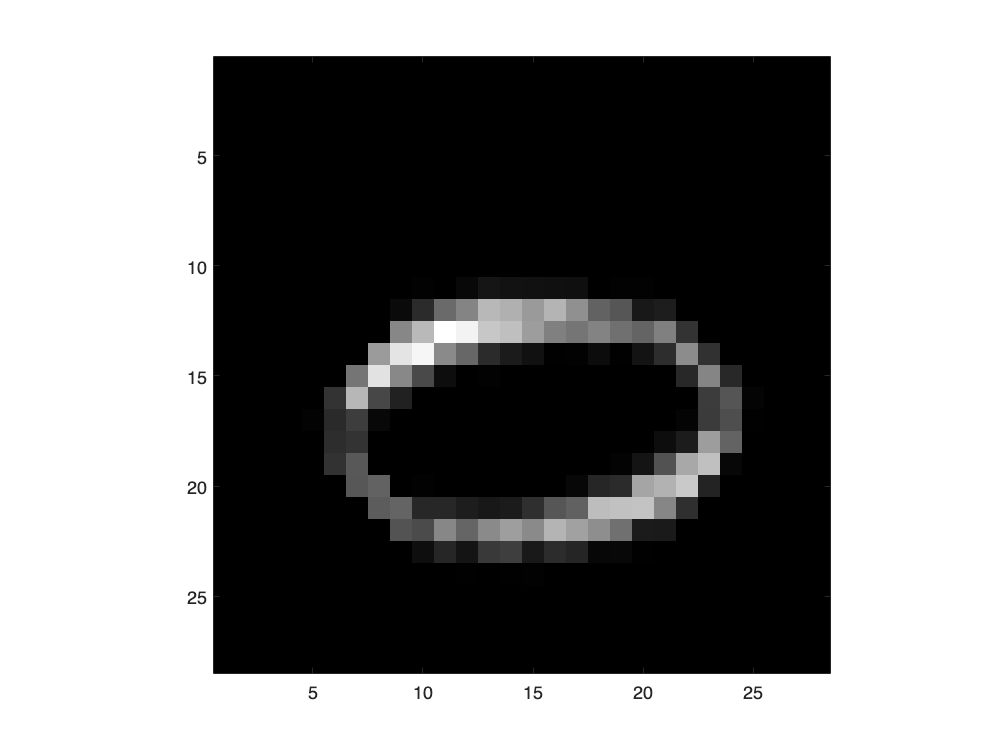

imagesc(wrong_digit_2), axis image, colormap gray

% This is a 7 which was classified as a 2
wrong_digit_3 = imgs_test(:,:,:,3741);

% The net is ≈60% certain that it is a 2...
net.predict(wrong_digit_3)   

ans = 1×10 single row vector
    0.0049    0.1620    0.5973    0.0023    0.1285    0.0045    0.0668    0.0282    0.0020    0.0035


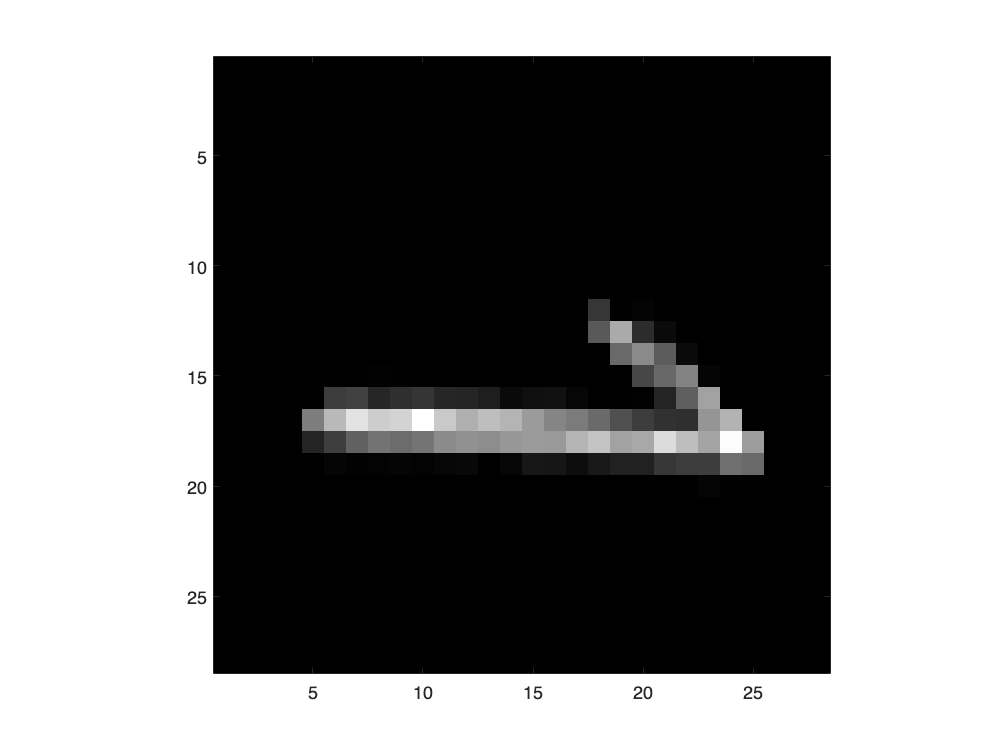


imagesc(wrong_digit_3), axis image, colormap gray

% Save images
imwrite(wrong_digit_1, 'mistaken_as_3.png')
imwrite(wrong_digit_2, 'mistaken_as_6.png')
imwrite(wrong_digit_3, 'mistaken_as_2.png')